## TOPIC 20: Simulations and Callbacks (cont'd)

ENGR105, 11/10/20

#### Revisiting simulations

We have already created and ran simulations in this class for a few different applications. Namely, we have simulated:

- The *number of turns* to obtain certain face values on a set of dice.

- The *number of turns* to obtain a number coin heads/tails in a row.

- The *outcome* from many interactions between **two individuals**, where an individual can act in cooperative, hostile, or more sophisticated manner.

As in these cases,** simulations** enable us to **study how a system evolves over time** and to **provide insight into possible outcomes**. Simulations are often simplified representations of something complex, and it is up to the scientist and engineer to determine appropriate rules, initial conditions, and boundary conditions.

#### Practice problem: simulating an infectious disease

Many simulations have been performed over the last year to describe viral transmission within a population. One recent simulation by the Washington Post modeled the transmission of SARS-CoV-2 amongst a population of *moving, interacting particles*:

[https://www.washingtonpost.com/graphics/2020/world/corona-simulator/](https://www.washingtonpost.com/graphics/2020/world/corona-simulator/)

Even in this *highly-simplified system*, the beneficial effects of **quarantining and social distancing** -- introducing "barriers" to social interactions resulted in fewer "super-spreader" events and the *flattening of the curve *of infections over time.

**Create a program that models the spread of an infectious disease between moving, interacting particles**. Your simulation should have the following rules:

- It should consider **two particles**: one *"healthy"* particle and one *"infected"* particle.

- Each particle can be represented *visually* as a **circle with a diameter of 1.**

- Each particle should move in **steps**, where in a given step each particle may change `x` position by a value randomly distributed on the interval `[-0.5,0.5]`.

- Each particle **may only move in the **`+/-`** x direction**. That is, the particle motion is 1-D.

- The particle motion is confined to the domain `[0,7]`: that is, any "part" of each particle may not move to an x value less than `0 `or an x value greater than `7`. 

- **The infected particle remains infected for the entire simulation**. The healthy particle remains healthy until the particles have "interacted," *i.e.* when the distance between particles is less than one particle diameter.

**Question**. By simulating ***many*** "sets" of particles, what are the **effects of social distancing**?

**PRO, Step 1****: ****P**lan, **P**repare, and **P**seudocode

Helpful tasks and thoughts:

- What do we want to create? A simulation of moving particles, where we record when the particles come within one particle diameter of each other. This is when the "infection" occurs.

- What is our ultimate goal? Run many simulations with and without "social distancing." How can we implement social distancing? One idea would be to have **one particle remain stationary** while the other can move.

- How can we break this up into manageable chunks? 

**Remember**: when faced with a large task like this, ***start small and gradually build up your solution***. Frequently check your output along the way. In this case, we will stop at defined checkpoints.

**PRO, Step 2****: **w**R**ite **R**ough (increments of code) and **R**efine 

***Checkpoint goal 1***: Produce a visualization of both particles.

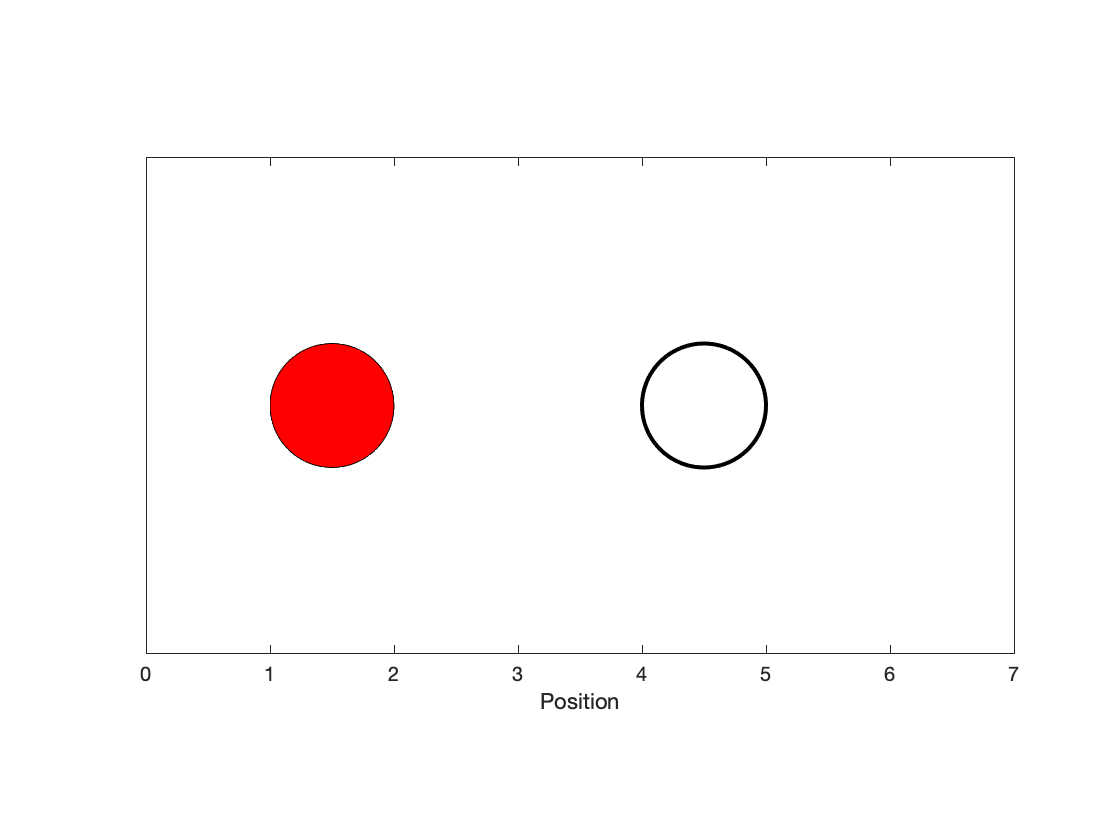

clear
%1) Vector representing the positions of the particles

pos = [1,4];

% particle one would be infected
%particle 2 is healthy

%3)produce visualization of the particles
g1 = axes;
axis image
xlim([0,7])
ylim([-2,2])
set(g1, 'ytick', [])
set(g1, 'Box', 'on')
xlabel('Position')

% Plot both particles initial positions 
p1 = rectangle('Position',[pos(1),-0.5,1,1],'Curvature',[1,1],'FaceColor','r');
p2 = rectangle('Position',[pos(2),-0.5,1,1],'Curvature',[1,1],'FaceColor','w','LineWidth',2);

***Checkpoint goal 2***: Produce a visualization of particles moving.

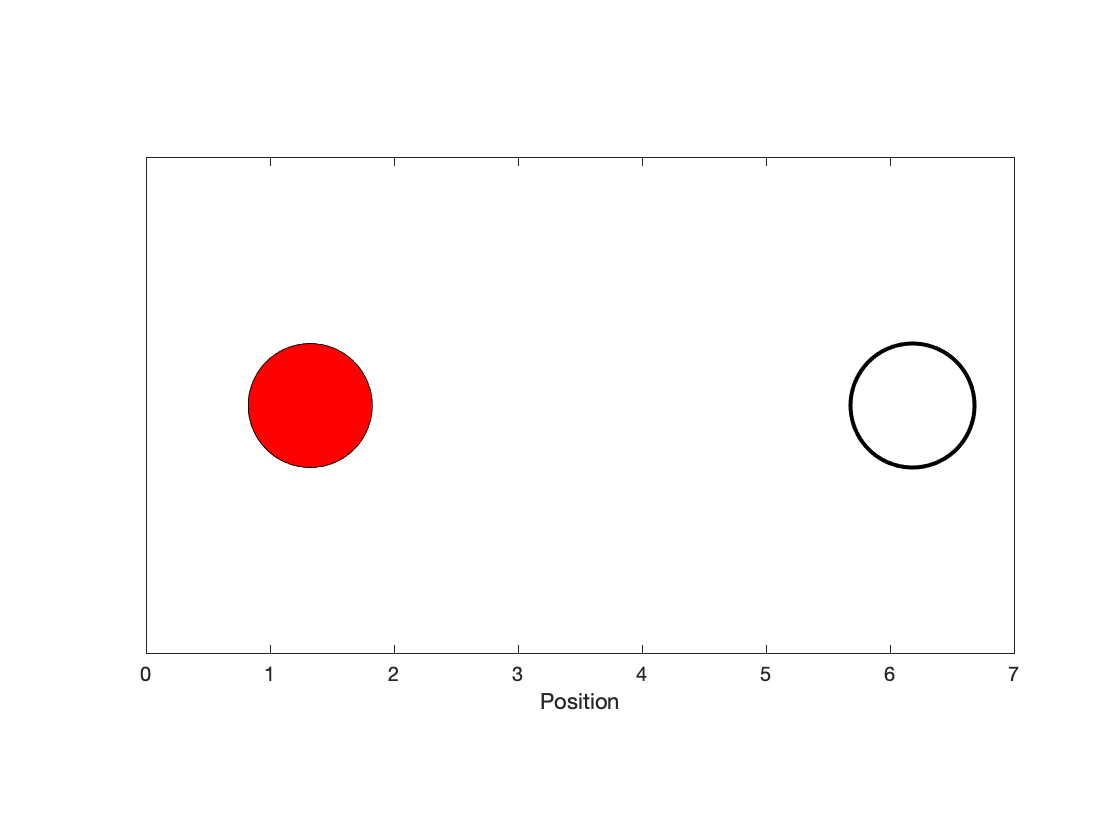

close all
%1) Vector representing the positions of the particles

pos = [1,4];

% particle one would be infected
%particle 2 is healthy

%3)produce visualization of the particles
g1 = axes;
axis image
xlim([0,7])
ylim([-2,2])
set(g1, 'ytick', [])
set(g1, 'Box', 'on')
xlabel('Position')

% Plot both particles initial positions 
p1 = rectangle('Position',[pos(1),-0.5,1,1],'Curvature',[1,1],'FaceColor','r');
p2 = rectangle('Position',[pos(2),-0.5,1,1],'Curvature',[1,1],'FaceColor','w','LineWidth',2);

% Step throught he simulation. In each step, update the particles positions
for k = 1:50
    
    % A) Create vector determining particle step
    d_k = (rand(1,2)-0.5);
    
    % B) Update particle position
    pos = pos + d_k;
    
    % C) Ensure particle doesn't move out of bounds 
    pos = max(min(pos,6),0);
    
    % D) Update visualization 
    p1.Position(1) = pos(1);
    p2.Position(1) = pos(2);
    
    % E) Pause Matlab
    pause(0.2)
end

***Checkpoint goal 3***: Incorporate interactions. Change healthy particle color when infection occurs

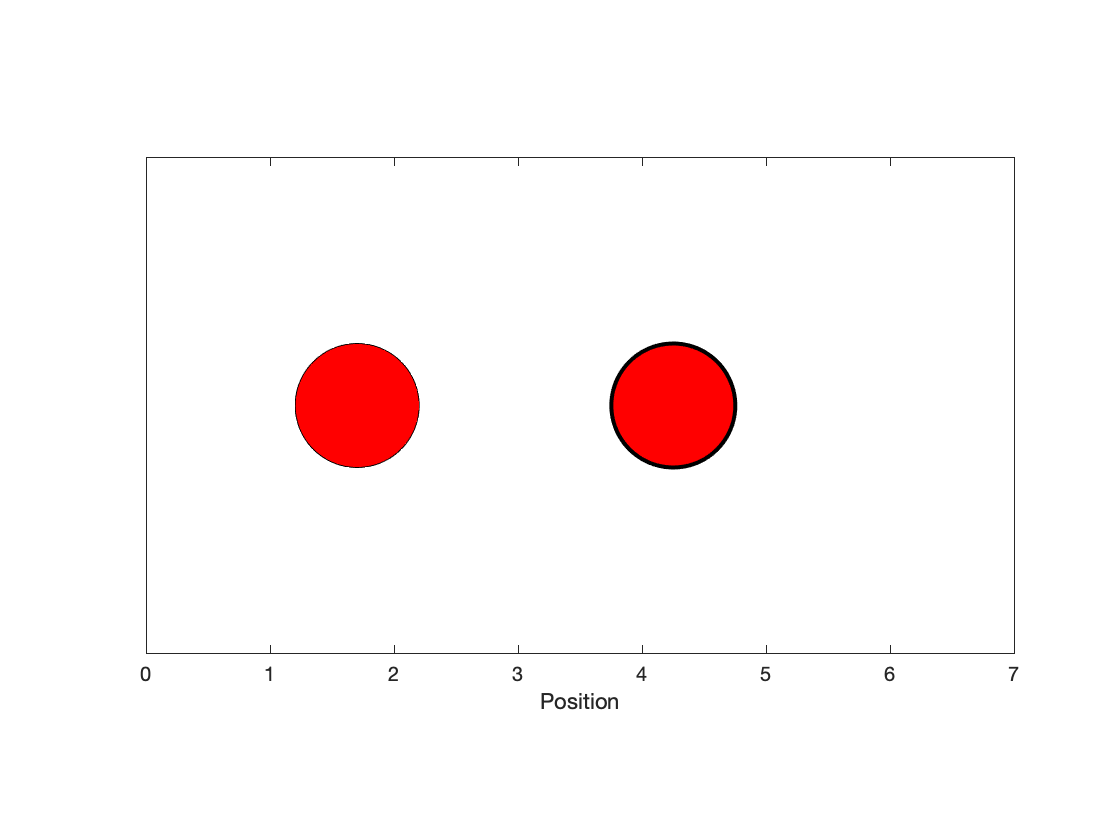

close all
%1) Vector representing the positions of the particles

pos = [1,4];

% particle one would be infected
%particle 2 is healthy

%3)produce visualization of the particles
g1 = axes;
axis image
xlim([0,7])
ylim([-2,2])
set(g1, 'ytick', [])
set(g1, 'Box', 'on')
xlabel('Position')

% Plot both particles initial positions 
p1 = rectangle('Position',[pos(1),-0.5,1,1],'Curvature',[1,1],'FaceColor','r');
p2 = rectangle('Position',[pos(2),-0.5,1,1],'Curvature',[1,1],'FaceColor','w','LineWidth',2);

% Step throught he simulation. In each step, update the particles positions
for k = 1:50
    
    % A) Create vector determining particle step
    d_k = (rand(1,2)-0.5);
    
    % B) Update particle position
    pos = pos + d_k;
    
    % C) Ensure particle doesn't move out of bounds 
    pos = max(min(pos,6),0);
    
    % Check if the particles interact
    if abs(pos(1) - pos(2)) < 1
        p2.FaceColor = 'r';
    end
    
    % D) Update visualization 
    p1.Position(1) = pos(1);
    p2.Position(1) = pos(2);
    
    % E) Pause Matlab
    pause(0.2)
end

***Checkpoint goal 4***: Make the simulation run *until* the particles interact.

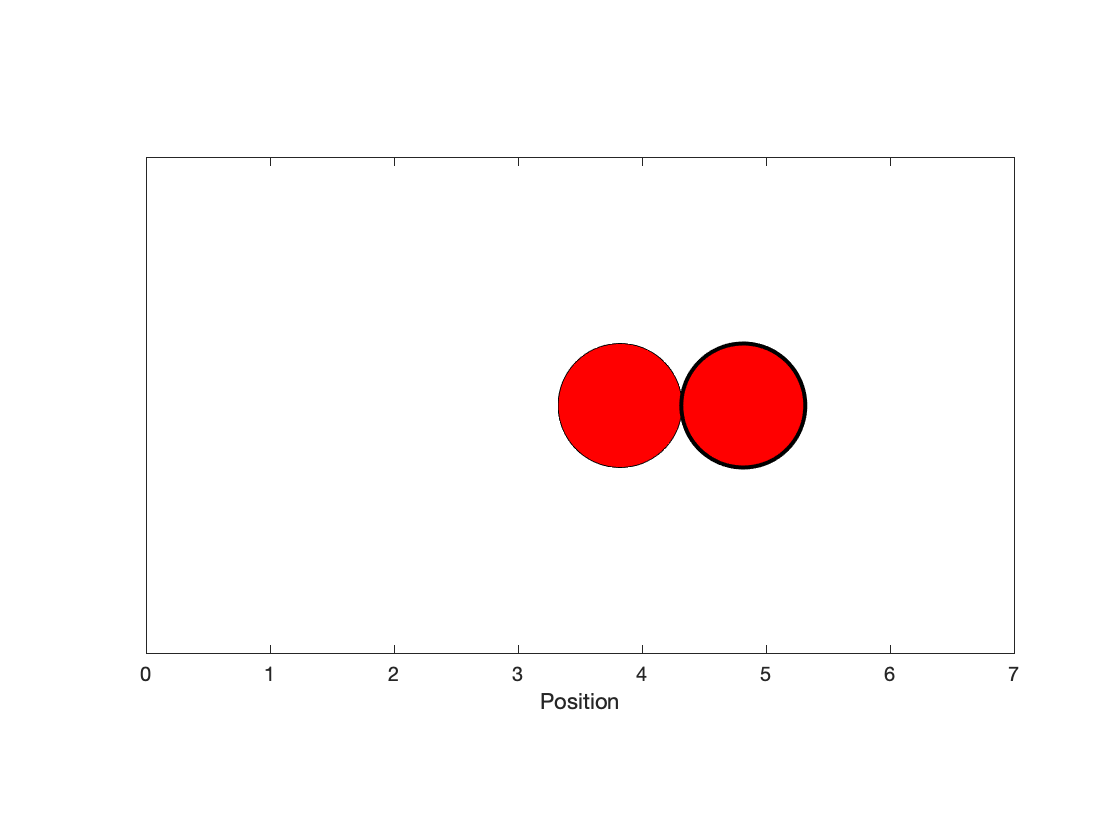

close all 

% 1) vector representing positions of two particles
pos = [1,4];

% 2) Define particle identities. 
% Particle 1 will be infected
% Particle 2 will intiially be healthy

% 3) Produce visualization of each particle
g1 = axes;
axis image
xlim([0,7])
ylim([-2,2])
set(g1, 'ytick', [])
set(g1, 'Box', 'on')
xlabel('Position')


% Plot both particles initial positions 
p1 = rectangle('Position',[pos(1),-0.5,1,1],'Curvature',[1,1],'FaceColor','r');
p2 = rectangle('Position',[pos(2),-0.5,1,1],'Curvature',[1,1],'FaceColor','w','LineWidth',2);


% Step through the simulation. In each step, update the particles positions
while abs(pos(1) - pos(2)) >=1
    % A) Create vector determining particle step
    d_k = (rand(1,2)-0.5);
    
    % B) Update particle position
    pos = pos + d_k;
    
    % C) Ensure particle doesn't move out of bounds 
    pos = max(min(pos,6),0);
    
    % Check if the particles interact
    if abs(pos(1) - pos(2)) < 1
        p2.FaceColor = 'r';
    end
    % D) Update visualization 
    p1.Position(1) = pos(1);
    p2.Position(1) = pos(2);
    
    % E) Pause Matlab
    pause(0.2)
end 

***Checkpoint goal 5***: We've produced a visualization of particle simulation. Ultimately, this visualization is not important. Since we will eventually compare normal particles to "socially distancing particles," we really just want to know the time required until the infection occurs. 

close all

% 1) vector representing positions of two particles
pos = [1,4];

% 2) Define particle identities. 
% Particle 1 will be infected
% Particle 2 will intiially be healthy

% Number of time steps until infection occurs
numSteps = 0;

% Step through the simulation. In each step, update the particles positions

% Step through the simulation. In each step, update the particles positions
while abs(pos(1) - pos(2)) >=1
    % A) Create vector determining particle step
    d_k = (rand(1,2)-0.5);
    
    % B) Update particle position
    pos = pos + d_k;
    
    % C) Ensure particle doesn't move out of bounds 
    pos = max(min(pos,6),0);
    
    % D) Update Counter
    numSteps = numSteps + 1;
end 

disp(numSteps)

   168



***Checkpoint goal 6***: Adapt the code so that we can observe the distribution of times until an infection occurs when 100 sets of simulations are performed.

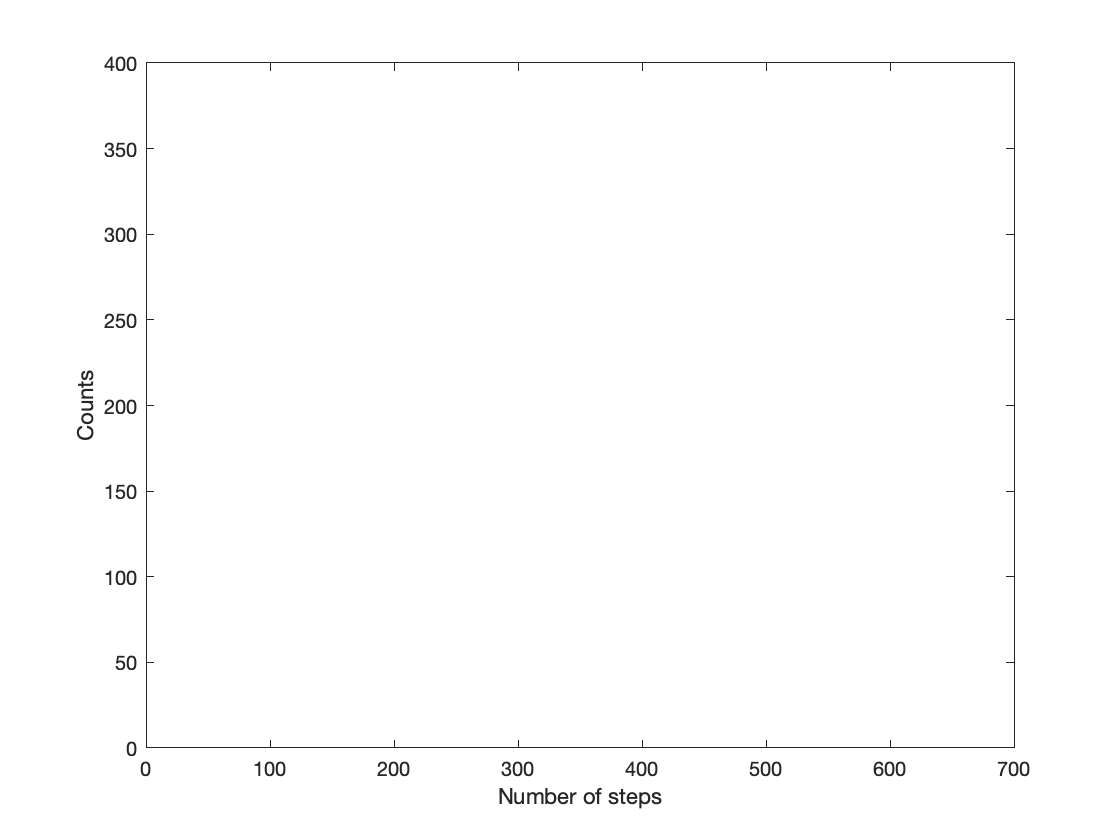

% Number of simulations 
numSim = 1000;

% Preallocate storage vector
numSteps = zeros(1,numSim);

% Repeat simulation numSim times
for k = 1:numSim
    %1) Vector representing positions of two particles
    pos = [1,4];

    % 2) Define particle identities. 
    % Particle 1 will be infected
    % Particle 2 will intiially be healthy
    
    % Step through the simulation. In each step, update the particles positions
    while abs(pos(1) - pos(2)) >=1
        % A) Create vector determining particle step
        d_k = (rand(1,2)-0.5);
        
        % B) Update particle position
        pos = pos + d_k;
        
        % C) Ensure particle doesn't move out of bounds 
        pos = max(min(pos,6),0);
        
        % D) Update Counter
        numSteps(k) = numSteps(k) + 1;
    end 

end

% Create visualization 
histogram(numSteps)
xlabel('Number of steps')
ylabel('Counts')
xlim([0,700])
ylim([0,400])

***Checkpoint goal 7***: Adapt the code so that we can observe the distribution for if one particle is **social distancing**. That is, assume the infected particle does not move in this simulation

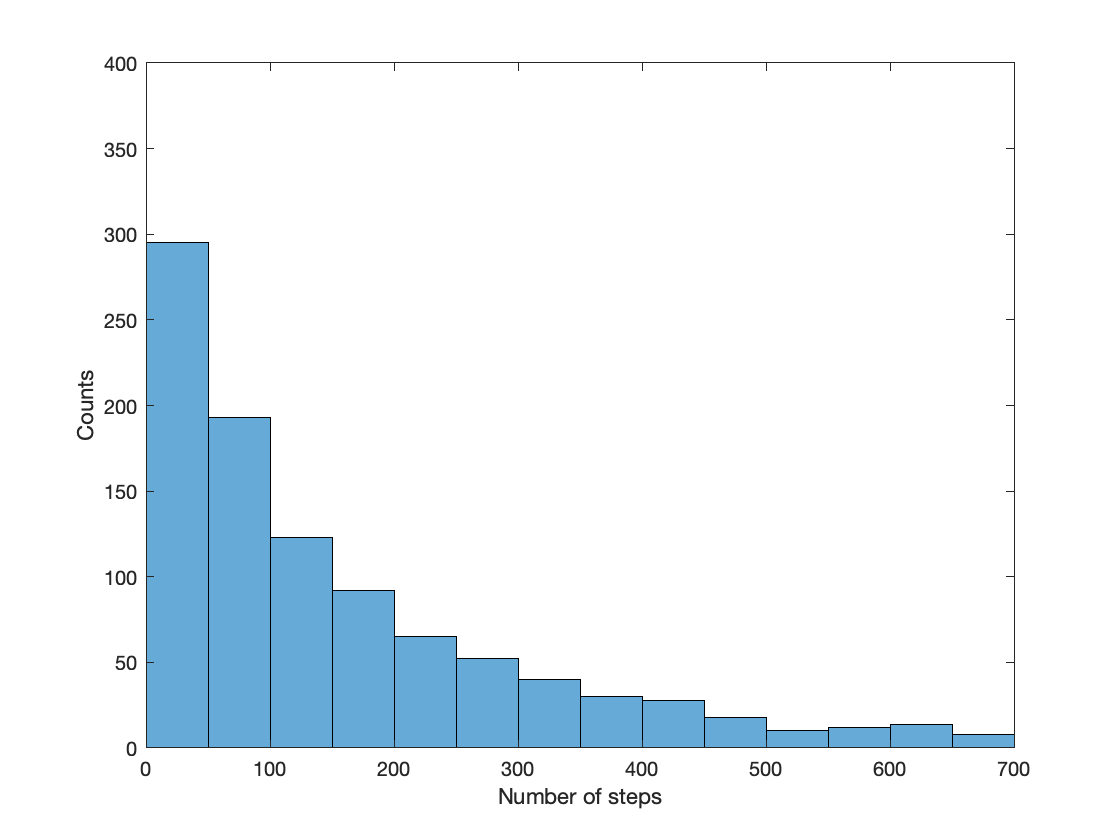

% Number of simulations 
numSim = 1000;

% Preallocate storage vector
numSteps = zeros(1,numSim);

% Repeat simulation numSim times
for k = 1:numSim
    %1) Vector representing positions of two particles
    pos = [1,4];

    % 2) Define particle identities. 
    % Particle 1 will be infected
    % Particle 2 will intiially be healthy
    
    % Step through the simulation. In each step, update the particles positions
    while abs(pos(1) - pos(2)) >=1
        % A) Create vector determining particle step
        d_k = (rand(1,2)-0.5).*[0,1];
        
        % B) Update particle position
        pos = pos + d_k;
        
        % C) Ensure particle doesn't move out of bounds 
        pos = max(min(pos,6),0);
        
        % D) Update Counter
        numSteps(k) = numSteps(k) + 1;
    end 

end

% Create visualization 
histogram(numSteps)
xlabel('Number of steps')
ylabel('Counts')
xlim([0,700])
ylim([0,400])

***Checkpoint goal 8***: Consolidate the above into one piece of code for comparing social distancing.

*Create a relevant function:*

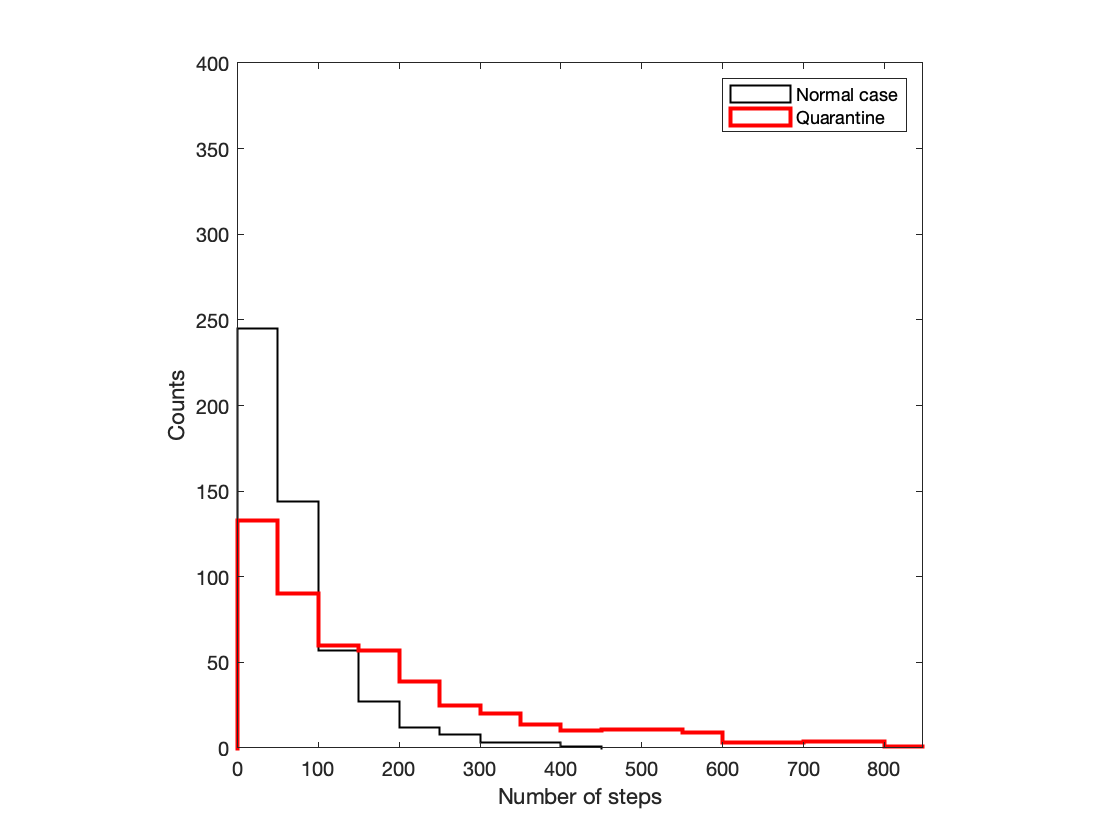

% Number of simulations 
numSim = 500;

% Preallocate storage vector
numSteps_norm = zeros(1,numSim);
numSteps_quar = zeros(1,numSim);

% Repeat simulation numSim times
for k = 1:numSim
    % Simulate normal
    numSteps_norm(k) = simulateDisease([1,1]);
    % Simulate quarantine
    numSteps_quar(k) = simulateDisease([0,1]);
end

% create visualization
h1 = histogram(numSteps_norm);
hold on
h2 = histogram(numSteps_quar);
hold off


% Visualization 
xlabel('Number of steps')
ylabel('Counts')
h1.BinWidth = 50;
h2.BinWidth = 50;
h1.DisplayStyle = 'stairs';
h2.DisplayStyle = 'stairs';
h2.LineWidth = 2;
h1.LineWidth = 1;
h2.EdgeColor = 'r';
h1.EdgeColor = 'k';
xlim([0,700])
ylim([0,400])
axis square
legend('Normal case', 'Quarantine', 'Location', 'Northeast')

**Takeaways**: 

- We have thus simulated how group dynamics can influence the spread of an infectious disease!

- How does this relate to what we might expect?

- When approaching problems, **start small and work up to a solution**.

#### Keyboard callbacks (key press)

Recall from last time that we produced an example where we can use the `arrow keys` to move a ball across the screen, while `'q'` closes the figure window. The following callback function is located at the end of the LiveScript document.

**Note**: callback functions do not support outputs.

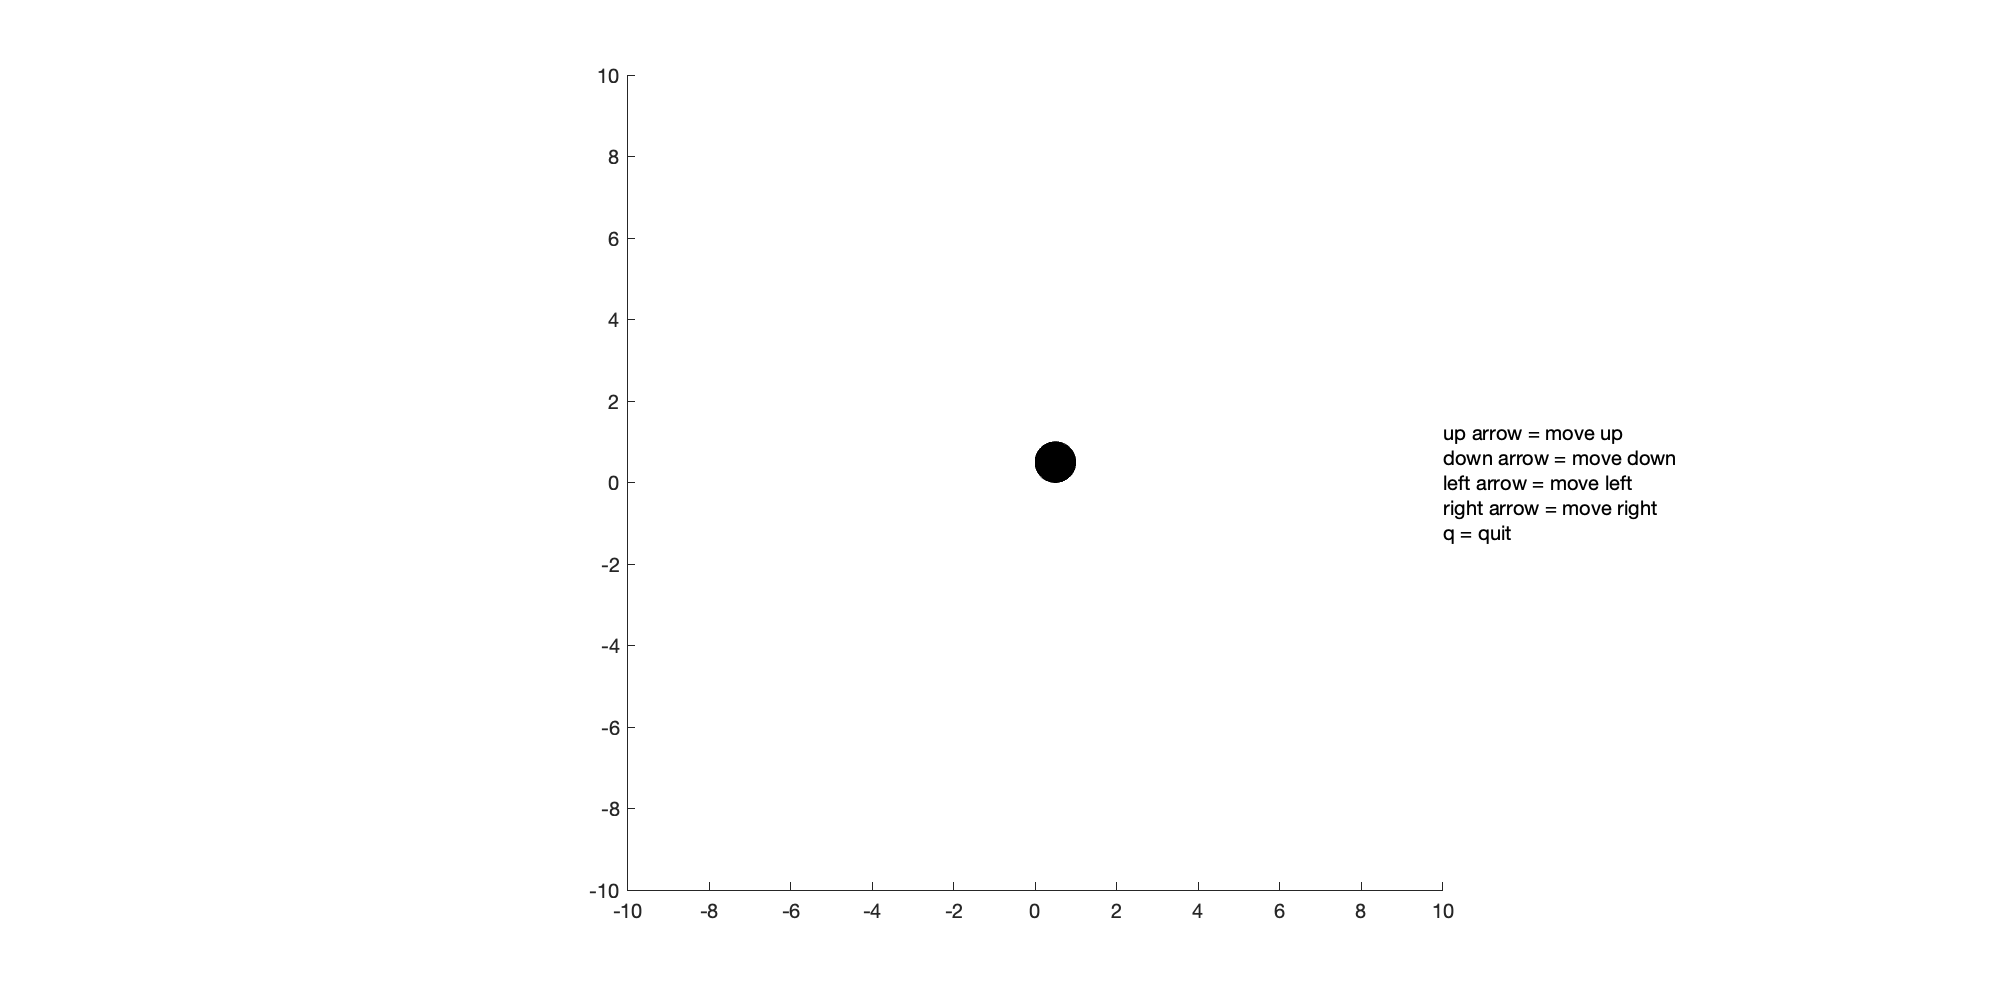

% Initialize the figure and assign the keyboard callback
% function.
hFig = figure('Position',[200,200,1000,500]);

% Specify plot formatting
text(10,0,{'up arrow = move up','down arrow = move down', ...
    'left arrow = move left','right arrow = move right','q = quit'})
axis square
xlim([-10,10])
ylim([-10,10])

% Create a "ball" and place it at [0,0] initially
hBall = rectangle('Position',[0,0,1,1],'Curvature',[1,1]);
hBall.FaceColor = 'k';

% Assign a keyboard call back


% Set figure to visible -> have it pop out so we can input the keyboard
% call backs
set(hFig,'Visible','on')

#### Keyboard callbacks (key release)

In the above example, something happens when we *press a button*. We can have something happen when we release a button. This can be specified using the `'KeyReleaseFcn'` field of the graphics object for the current figure.

**Example 3.** **Produce a game where you must keep moving the ball.** If the player doesn't move for ~ 1 second, display "`Game Over`." Furthermore, make the "ball" become "whiter" as the game approaches the end game scenario.

To create this solution, we must create:

- A function to be assigned to the *key press*

- A function to be assigned to the *key release*

close all % Close previous windows

% Initialize the figure and assign the keyboard callback
% function.
hFig = figure('Position',[200,200,1000,500]);

% Specify plot formatting
text(10,0,{'up arrow = move up','down arrow = move down', ...
    'left arrow = move left','right arrow = move right','q = quit'})
axis square
xlim([-10,10])
ylim([-10,10])

% Create a "ball" and place it at [0,0] initially
hBall = rectangle('Position',[0,0,1,1],'Curvature',[1,1]);
hBall.FaceColor = 'k';  % Default color is black

% Assign a keyboard call back for when a buttom is pressed

% Assign a keyboard call back for when a button is release


% Set figure to visible -> have it pop out so we can input the keyboard
% call backs
set(hFig,'Visible','on')

**Challenge**. Can you create modifications to the code so that:

- The radius of the ball resets on a key press but increases as the color becomes whiter?

- You want the ball to avoid regions of the playable area?

- At the end ot the game, the game window closes and the new window appears that says "Game Over?"

**Takeaway note:** *in these cases (and below), callback functions are not compatible with outputs.*

#### Mouse callbacks

Similarly to assigning keyboard callbacks, one can assign callback functions to **mouse operations** as function handles to the appropriate field of a graphics handle object. In particular, we will discuss the following fields associated with mouse operations:

- `WindowButtonMotionFcn - `the mouse pointer is moved

- `WindowButtonDownFcn - `the mouse button is pressed

- `WindowButtonUpFcn - `the mouse button is released

**Example 1**. Create a script that tracks the mouse cursor across a figure windows and reports the x and y position at the tip of the cursor.

*Callback function:*

This will utilize a callback associated with the `'WindowButtonMotionFcn'` field, which **executes whenever motion on the figure is detected**.

**Note**: this utilizes `get(``gca``,``'``CurrentPoint``'``)` in the callback function, which reports the location of the mouse button as a `2x3` matrix:

- The 1st row, 1st column of the matrix is the x position of the click

- The 1st row, 2nd column of the matrix is the y position of the click

*Incorporating this into a script:*

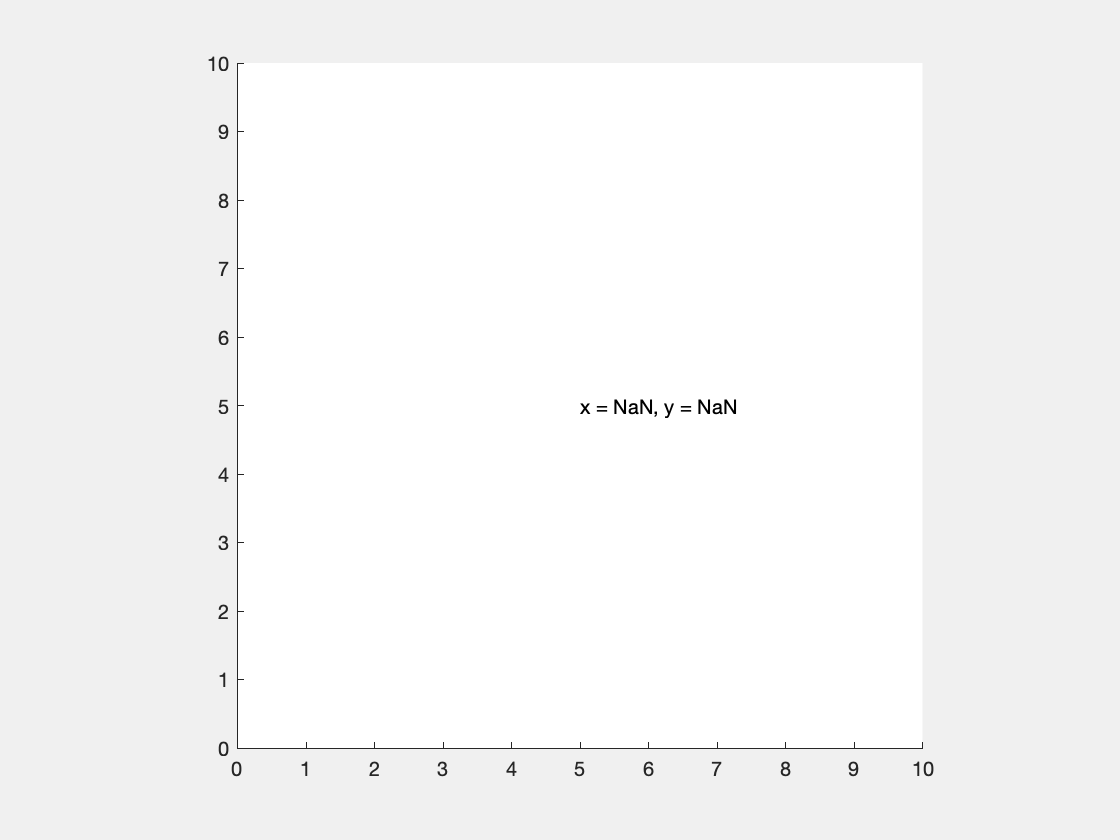

close all % close previous figures

% Create a figure to be associated with the mouse callback
hFig1 = figure('Visible','on');
axis equal
xlim([0,10])
ylim([0,10])

% Initialize a text object for displaying coordinates
g = text(5,5,'x = NaN, y = NaN');


% Assign mouse callback function



**Mouse button clicks** can be registered in a figure window using the `WindowButtonDownFcn` callback. In the following, you can observe the SelectionType for different mouse clicks.

close all

% Create a figure and establish the callback associated with a
% mouse button press.
figure('WindowButtonDownFcn',@click,'Visible','on')

- `'normal'` - left mouse button click

- `'alt'` - right mouse button click

- `'extend'` - middle mouse button click

- `'open'` - double click

**Example 2**. Create an **interactive plot **where points can be added to the plot based on the location of the mouse cursor when pressing any mouse button.

*Callback function:*

**Note**: the above  uses `drawnow`. `drawnow` is equivalent to `pause(`*<shortest time based on your computer's processor>*`)` and updates figures and processes any pending callbacks. Use this command if you modify graphics objects and want to see the updates on the screen immediately.

*Incorporating this into a script:*

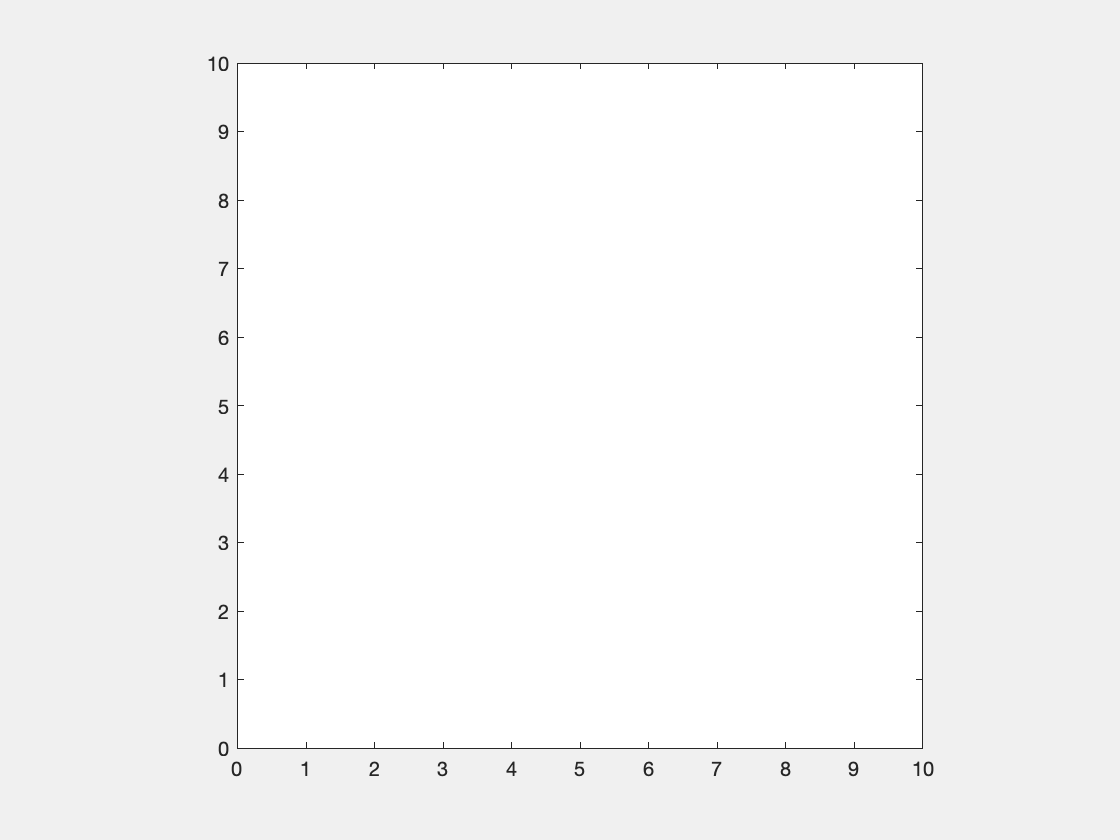

close all

% Create a figure with mouse button press callback and plot
% NaNs (nothingness) on the figure.
hFig2 = figure('Visible','on');
h = plot(NaN,NaN,'ro-','MarkerFaceColor','r','MarkerSize',5);

% Assign callback function


% Graphical parameters
axis equal
xlim([0,10])
ylim([0,10])

**Example 3**. Create an similarly **interactive plot that **populates **lines of different colors** depending on if the left or right mouse button is clicked. 

*Callback function:*

*Incorporating into a script:*

close all % Delete previous

% Create a figure with mouse button press callback
hFig3 = figure('Visible','on');

% Plot each color line, initially as NaN. The first plot (handle = hRed)
% hold the red points and the second plot (handle = hGreen) hold
% the green points.
hRed = plot(NaN,NaN,'ro-','MarkerFaceColor','r','MarkerSize',5);
hold on
hGreen = plot(NaN,NaN,'go-','MarkerFaceColor','g','MarkerSize',5);
hold off

% Assign callback function


axis square
xlim([0,10])
ylim([0,10])

**Functions for this Lecture**

- Practice problem: infectious disease

function numSteps = simulateDisease(moveModifier)
    % Inputs: 
    % [0,1]: particle 1 is in quarantine 
    % [1,1]: particles can move freely
    % [1,0]: particle 2 is in quarantine
    
    % 1) vector representing posititions of two particles
    pos = [1,4];
    
    % 2) Define particle identities
    % Particle 1 will be infected
    % Particle 2 will initially be healthy
    
    % Define counter for steps
    numSteps = 0;
    
    % Step through the simulation. in each step update the particles
    % positions 
    while abs(pos(1) - pos(2)) >=1
        
        % A) Create vector determining particle step
        d_k = (rand(1,2)-0.5).*moveModifier;
        
        % B) Update particle position
        pos = pos + d_k;
        
        % C) Ensure particle doesn't move out of bounds
        pos = max(min(pos,6),0);
        
        % D) Update counter
        numSteps = numSteps + 1;
    end
end


- Moving ball example (from before)

function DoWhenKeyIsPressed(~,eventdata,hBall)
    % Utilizes keypresses to move the x/y coordinates of the
    % ball or closes the figure.
    
    % Movement increment
    inc = 0.3; 

    % Move up
    if strcmp(eventdata.Key,'uparrow')
        hBall.Position(2) = min(hBall.Position(2)+inc,9);
        
    % Move down
    elseif strcmp(eventdata.Key,'downarrow')
        hBall.Position(2) = max(hBall.Position(2)-inc,-10);
    % Move left
    elseif strcmp(eventdata.Key,'leftarrow') 
        hBall.Position(1) = max(hBall.Position(1)-inc,-10);
    % Move right
    elseif strcmp(eventdata.Key,'rightarrow')   
        hBall.Position(1) = min(hBall.Position(1)+inc,9);
    % Close figure
    elseif strcmp(eventdata.Key,'q')  
        close()
    % Display invalid keystroke
    else
        disp('Key not mapped')
    end
end

- Example 3: when key is pressed

function ex3_keyPress(~,eventdata,hBall)
    % Utilizes keypresses to move the x/y coordinates of the
    % ball or closes the figure.
    
    % Movement increment
    inc = 0.3; 

    % Reset FaceColor to be black
    hBall.FaceColor = 'k';
    
    % Move up
    if strcmp(eventdata.Key,'uparrow')
        hBall.Position(2) = min(hBall.Position(2)+inc,9);
        
    % Move down
    elseif strcmp(eventdata.Key,'downarrow')
        hBall.Position(2) = max(hBall.Position(2)-inc,-10);
    % Move left
    elseif strcmp(eventdata.Key,'leftarrow') 
        hBall.Position(1) = max(hBall.Position(1)-inc,-10);
    % Move right
    elseif strcmp(eventdata.Key,'rightarrow')   
        hBall.Position(1) = min(hBall.Position(1)+inc,9);
    % Close figure
    elseif strcmp(eventdata.Key,'q')  
        close()
    % Display invalid keystroke
    else
        disp('Key not mapped')
    end
end

- Example 3: key is released

function ex3_keyRelease(~,~,hBall)
    % Function to be executed when key is released. Takes a graphics object
    % corresponding to the ball as an input

    % Increase the whiteness of the ball until it becomes fully white
    while hBall.FaceColor(1) < 0.9
        
        % Make FaceColor whiter
        hBall.FaceColor = min(hBall.FaceColor + 0.1,1);
    
        % Pause for 100 ms
        pause(0.1)
    end
    
    % If ~1 second passes without moving, game over
    t1 = text(-10,0,'GAME OVER');
    t1.FontSize = 50;
    t1.Color = 'r';
    
end

- Mouse callback - Depict position of mouse on screen

function moveText(~,~,g)
    % The mouse button motion callback.
    
    % Get the current mouse location.
    pos = get(gca, 'CurrentPoint');
    x = pos(1,1); y = pos(1,2);
    
    % Update the text object readout to the current location
    % and place its location at the cursor tip.
    g.String = ['x = ',num2str(x),', y = ',num2str(y)];
    g.Position = [x, y, 0]; % position 0 in 3rd dimension
end

- Mouse callback - display selection type, depending on mouse click

function click(h,~)
    % The callback for a mouse button press. Print the mouse
    % button identifier to the command window.
    h.SelectionType
end
 

- Mouse callback - select points and plot on a graph

function plotPoints1(~,~,h)
    % Call back function for updating a plot
    
    % Get the current mouse location 
    pos = get(gca,'CurrentPoint');
   
    % Update the plot with the new position
    h.XData(end+1) = pos(1,1);
    h.YData(end+1) = pos(1,2);
    drawnow
end

- Mouse callback - select points and plot depending on right click or left click

function plotPoints2(h,~,hRed,hGreen)
    % Callback function for updating a plot with multiple colored points
    
    % Get the current mouse location.
    pos = get(gca, 'CurrentPoint');
    
    % If a left click: add to the red plot
    if strcmp(h.SelectionType,'normal')
        
        % Add to the data in the red plot
        hRed.XData(end+1) = pos(1,1); 
        hRed.YData(end+1) = pos(1,2);
        drawnow

    % If a right click: add to the green plot
    elseif strcmp(h.SelectionType,'alt')
        
        % Add to the data in the red plot
        hGreen.XData(end+1) = pos(1,1); 
        hGreen.YData(end+1) = pos(1,2);
        drawnow
        
    end
end